save ('TestX_30deg_PID', "PID")
save ('TestX_30deg_WO_PID', "WO_PID")

close all; clear;

load TestX_30deg_PID.mat
PID = out;

load TestX_30deg_WO_PID.mat
WO_PID = out;

ceX = PID.simout1.data;
angleX = (PID.simout.data)*(-1);
GX = 1.72;
VX = (11.4/255)*GX*ceX;

t_PID = PID.tout;

WO_ceX = WO_PID.simout1.data;
WO_angleX = (WO_PID.simout.data)*(-1);
WO_VX = (11.4/255)*GX*WO_ceX;

t_WO = WO_PID.tout;

t_WO =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


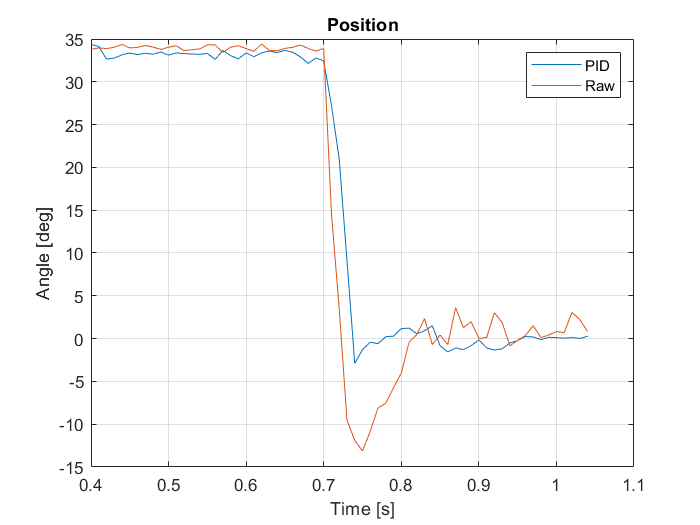

plot(t_PID,angleX)
hold on;
plot(t_PID, WO_angleX)
hold off
title('Position')
xlabel('Time [s]'), ylabel('Angle [deg]')
grid
legend('PID','Raw')

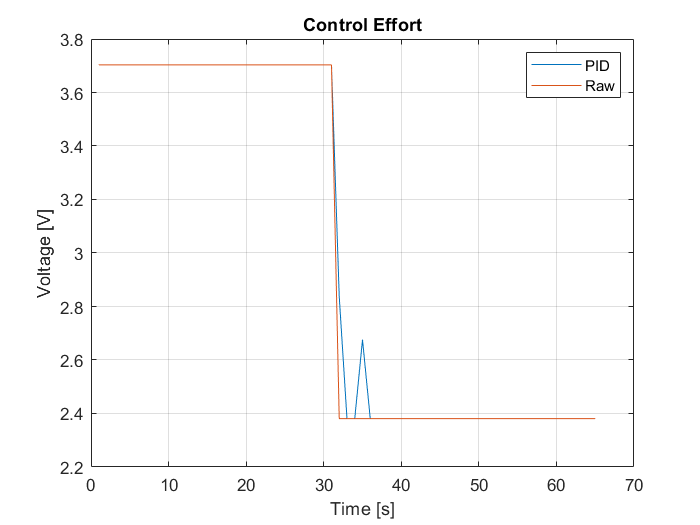

plot(VX)
hold on;
plot(WO_VX)
hold off
title('Control Effort')
xlabel('Time [s]'), ylabel('Voltage [V]')
grid
legend('PID','Raw')

save ('TestX_30deg_PID', "y_PID")
save ('TestX_30deg_WO_PID', "y_WO_PID")

load TestY_30deg_WO_PID.mat
y_WO_PID = out;

load TestY_30deg_PID.mat
y_PID = out;

ceY = y_PID.simout3.data;
angleY = (y_PID.simout2.data)*(-1);
if angleY > 0
    GY = 3;
else
    GY = 1;
end
VY_PID = (11.4/255)*GY*ceY;

tY_PID = y_PID.tout;

WO_ceY = y_WO_PID.simout3.data;
WO_angleY = (y_WO_PID.simout2.data)*(-1);
if WO_angleY > 0
    GY = 3;
else
    GY = 1;
end
VY_WO_PID = (11.4/255)*GY*WO_ceY;

tY_WO_PID = y_WO_PID.tout;

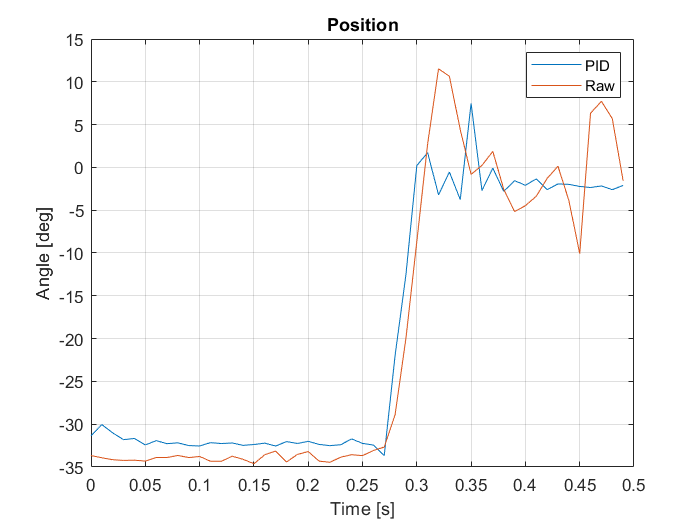

plot(tY_WO_PID,angleY)
hold on
plot(tY_WO_PID,WO_angleY)
hold off
title('Position')
xlabel('Time [s]'), ylabel('Angle [deg]')
grid
legend('PID','Raw')

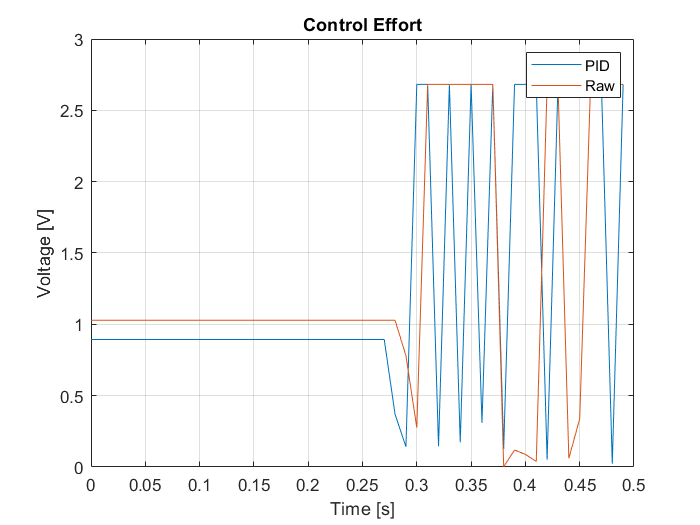

plot(tY_WO_PID,VY_PID)
hold on
plot(tY_WO_PID,VY_WO_PID)
hold off
title('Control Effort')
xlabel('Time [s]'), ylabel('Voltage [V]')
grid
legend('PID','Raw')

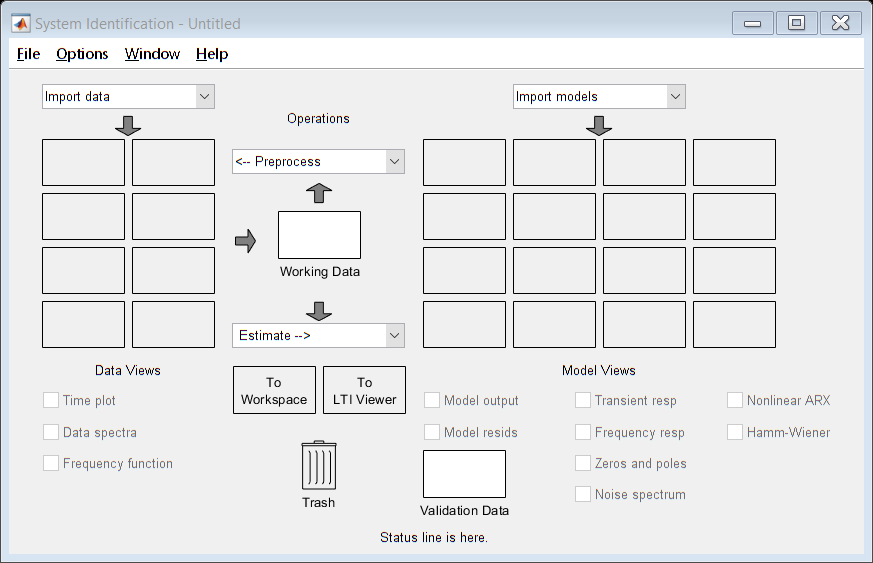


systemIdentification